## Wighted Hinfnorm 

The H-inf norm is tested with the weighting function W_Delta

obtain system description

clc
clear

disp("Initilization Procedure")

Initilization Procedure


model.Parameters

param = control.calculateOperatingPoint(param);

Calculate Operating Point for T_a = 293.150000 [K]


param = model.calculateModel(param);

Calculate bilinear model matrices
Calculate linearisation decoupled
Calculate linearisation coupled
Testing controlability
Testing T_ref


simtime = 10*60;

obtain controller gain K from Design procedure 2. 

param.ctrl.Ks = control.DesignProcedure2(param,0,0);

Evaluation of design procedure 2 
Q is positive definite


ans =     0.0016    0.0016    0.0016    0.0150    0.2695    0.2715    0.2718    0.2750    2.7455    3.9375    4.0292    4.1667


Gamma is found to be:


ans = 1.0203

Eigenvalues of the decoupled systems are all negative 


ans =    -4.2846   -2.7730   -0.0498  -31.1007   -4.0327   -0.0204  -35.3673   -3.9953   -0.0204  -29.1618   -3.9953   -0.0195


Eigenvalues of the coupled systems are all negative 


ans =   -82.1771  -71.2049  -56.7517   -6.7556   -3.7411   -4.0336   -3.9960   -3.9961   -0.0497   -0.0195   -0.0204   -0.0204


K = blkdiag(param.ctrl.Ks(:,:,1),param.ctrl.Ks(:,:,2),param.ctrl.Ks(:,:,3),param.ctrl.Ks(:,:,4));

#### Plot and save wighted M

uses the filter specefied in equation 5.24      

s = tf('s')

s =
 
  s
 
Continuous-time transfer function.
Model Properties




unc = [param.model.B(1,:)-param.model.B_Bar(1,:);
        param.model.B(4,:)-param.model.B_Bar(4,:)
        param.model.B(7,:)-param.model.B_Bar(7,:)
        param.model.B(10,:)-param.model.B_Bar(10,:)];
Wdelta = unc*tf([1],[1])

Wdelta =
 
  From input 1 to output...
   1:  -0.1717
 
   2:  0.03592
 
   3:  0.03366
 
   4:  0.03104
 
  From input 2 to output...
   1:  0.01306
 
   2:  -0.1954
 
   3:  0.02816
 
   4:  0.02596
 
  From input 3 to output...
   1:  0.007648
 
   2:  0.01759
 
   3:  -0.2016
 
   4:  0.03086
 
  From input 4 to output...
   1:  0.009235
 
   2:  0.02124
 
   3:  0.04041
 
   4:  -0.1751
 
Static gain.


WdeltaTF2SS = ss(Wdelta);

WdeltaSS.A = zeros(4)

WdeltaSS = struct with fields:
    A: [4×4 double]


WdeltaSS.B = zeros(4);
WdeltaSS.C = zeros(4);
WdeltaSS.D = WdeltaTF2SS.D

WdeltaSS = struct with fields:
    A: [4×4 double]
    B: [4×4 double]
    C: [4×4 double]
    D: [4×4 double]






Cy = eye(12);

Am = [param.model.A+param.model.B*K*Cy, zeros(12,4);
      WdeltaSS.B*K*Cy, WdeltaSS.A];

Bm = [param.model.B;
      zeros(4,4)]; 

Cm = [WdeltaSS.D*K*Cy, WdeltaSS.C];

Dm = [zeros(4,4)];

M = Cm/(s*eye(16)-Am)*Bm+Dm;
disp("Largest singular value |M_W|_\infty")

Largest singular value |M_W|_\infty


max(max(sigma(M)))

ans = 0.2282

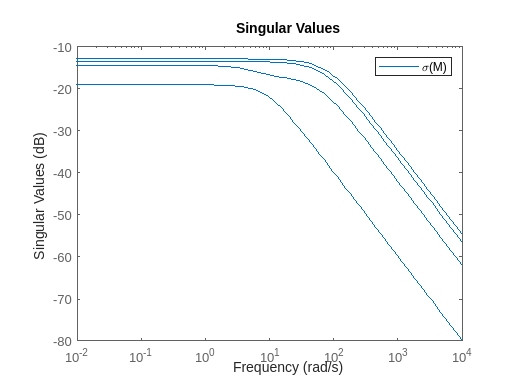

figure()
sigma(M)
legend("\sigma(M)")
saveas(gcf,"Images/SigamMWighted","epsc")

#### Plot and save non-wighted M

s = tf('s')

s =
 
  s
 
Continuous-time transfer function.
Model Properties



% Create a unity gain feedforward filter
Wdelta = eye(4)*tf([1],[1])

Wdelta =
 
  From input 1 to output...
   1:  1
 
   2:  0
 
   3:  0
 
   4:  0
 
  From input 2 to output...
   1:  0
 
   2:  1
 
   3:  0
 
   4:  0
 
  From input 3 to output...
   1:  0
 
   2:  0
 
   3:  1
 
   4:  0
 
  From input 4 to output...
   1:  0
 
   2:  0
 
   3:  0
 
   4:  1
 
Static gain.
Model Properties


WdeltaTF2SS = ss(Wdelta);
WdeltaSS.A = zeros(4);
WdeltaSS.B = zeros(4);
WdeltaSS.C = zeros(4);
WdeltaSS.D = WdeltaTF2SS.D

WdeltaSS = struct with fields:
    A: [4×4 double]
    B: [4×4 double]
    C: [4×4 double]
    D: [4×4 double]




Cy = eye(12);
Am = [param.model.A+param.model.B*K*Cy, zeros(12,4);
      WdeltaSS.B*K*Cy, WdeltaSS.A];

Bm = [param.model.B;
      zeros(4,4)]; 

Cm = [WdeltaSS.D*K*Cy, WdeltaSS.C];

Dm = [zeros(4,4)];

M = Cm/(s*eye(16)-Am)*Bm+Dm;
disp("Largest singular value |M_W|_\infty")

Largest singular value |M_W|_\infty



max(max(sigma(M)))

ans = 1.0141

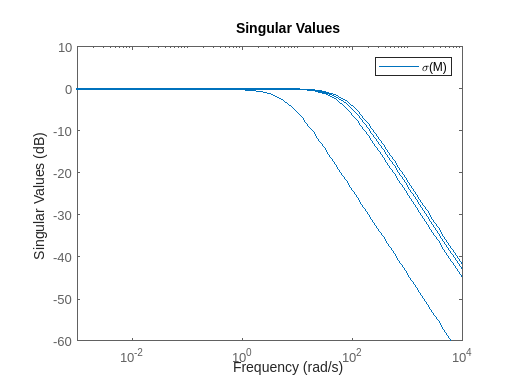

figure()
sigma(M)
legend("\sigma(M)")

saveas(gcf,"Images/SigamMNonWighted","epsc")